# Teensy IMU Data Logger Post Processing

2/19/2026

Mitchell Farah

## Validate timing

% meta = jsonToStruct('binFiles\imuLog_06.json');
% [seq, ts] = readSeqTs_chunkAware('binFiles\imuLog_06.bin', meta.buffer_config.chunk_bytes, meta.file_metadata.sample_count);
% 
% find(diff(double(seq))~=1,1,'first')
% seq(5953:5960)


## Load the data

% Call the decodeImuLog.m function with the imuLog_##. this will load the
% imu raw data in the bin file and the run information from the .json file
data = decodeImuLog("binFiles\imuLog_51.bin",10);

## quantify # of duplicate time samples:

t = double(data.raw.ts_us);     % or log.raw.ts_us
dt = diff(t);

z = find(dt == 0);
fprintf('Duplicate timestamps: %d (%.4f%% of intervals)\n', numel(z), 100*numel(z)/numel(dt));

Duplicate timestamps: 0 (0.0000% of intervals)



% Are duplicates isolated or in runs?
runLen = diff([0; z; numel(dt)+1]);
% (this isn't perfect; better is run-length encoding, but quick check:)
disp("First few duplicate indices:");

First few duplicate indices:


disp(z(1:min(20,end)));

% Show a small window around first duplicate
if ~isempty(z)
    i = z(1);
    disp(table(data.raw.seq(i-2:i+3), t(i-2:i+3), 'VariableNames', {'seq','ts_us'}));
end

## Plot the data:

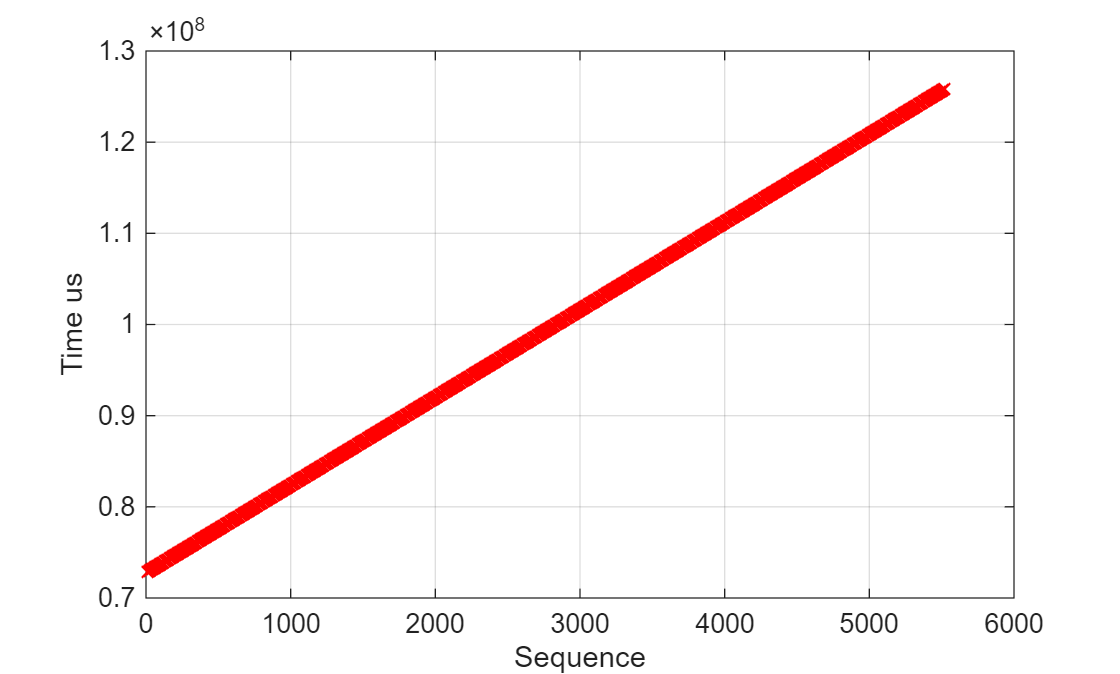

maxTime = max(data.timetable.Time);
mintime = min(data.timetable.Time);
maxSeq = max(data.raw.seq);
imuTT = data.timetable;

%plot sequence vs time
figure;
plot(data.raw.seq,data.raw.ts_us,'-rx');
xlabel('Sequence');
ylabel('Time us');
grid on;

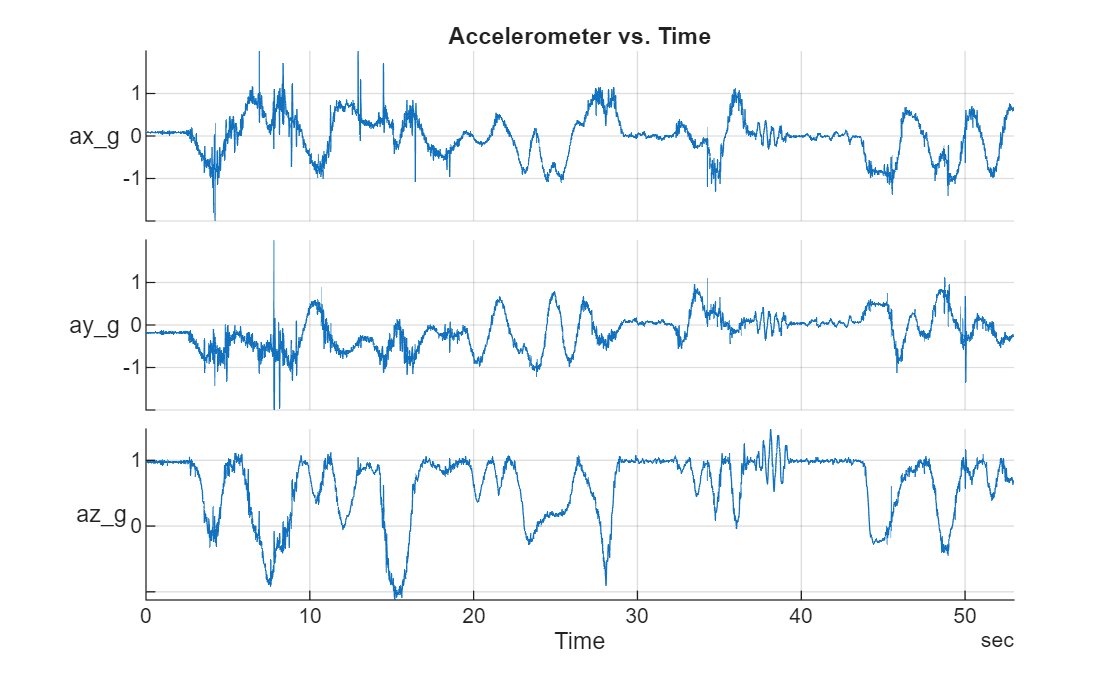



%accel vs time
figure;
stackedplot(imuTT,["ax_g","ay_g","az_g"]);
title('Accelerometer vs. Time');
grid on;

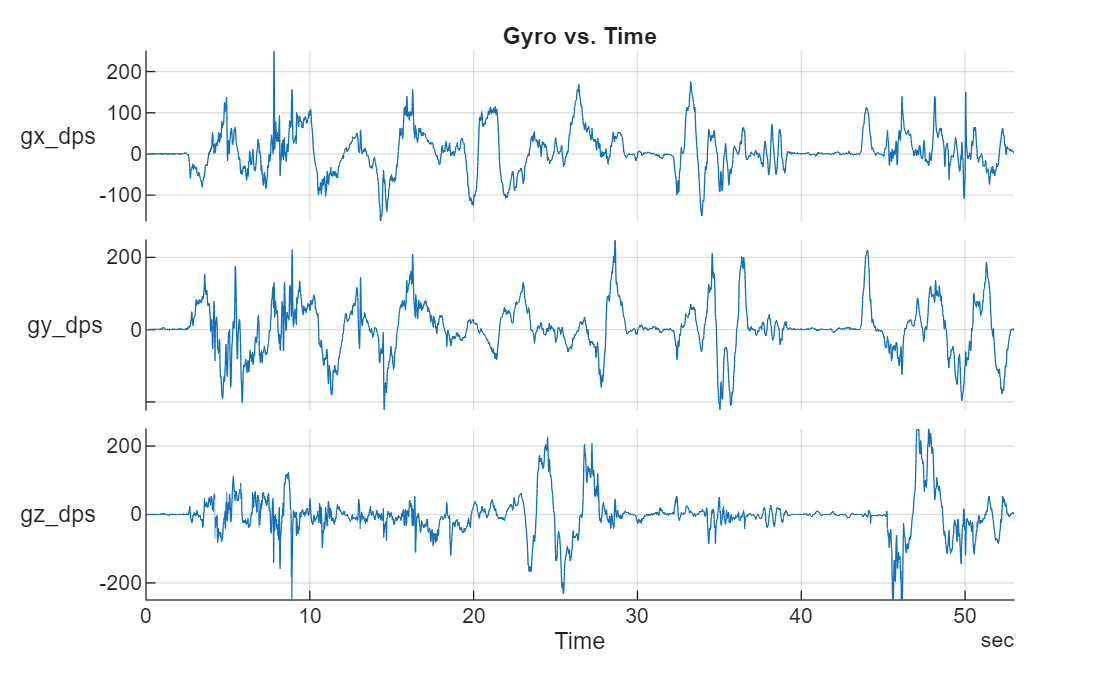



% Gyro vs time
figure;
stackedplot(imuTT,["gx_dps","gy_dps","gz_dps"]);
title('Gyro vs. Time');
grid on;

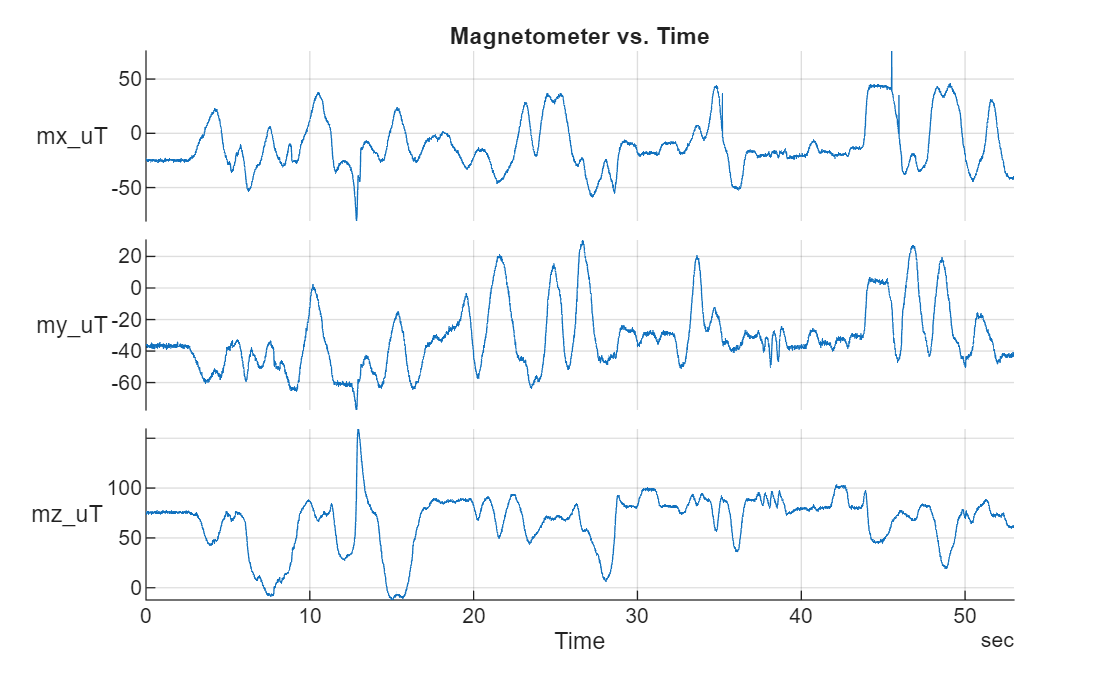

% Magnetometer vs time
figure;
stackedplot(imuTT,["mx_uT","my_uT","mz_uT"]);
title('Magnetometer vs. Time');
grid on;

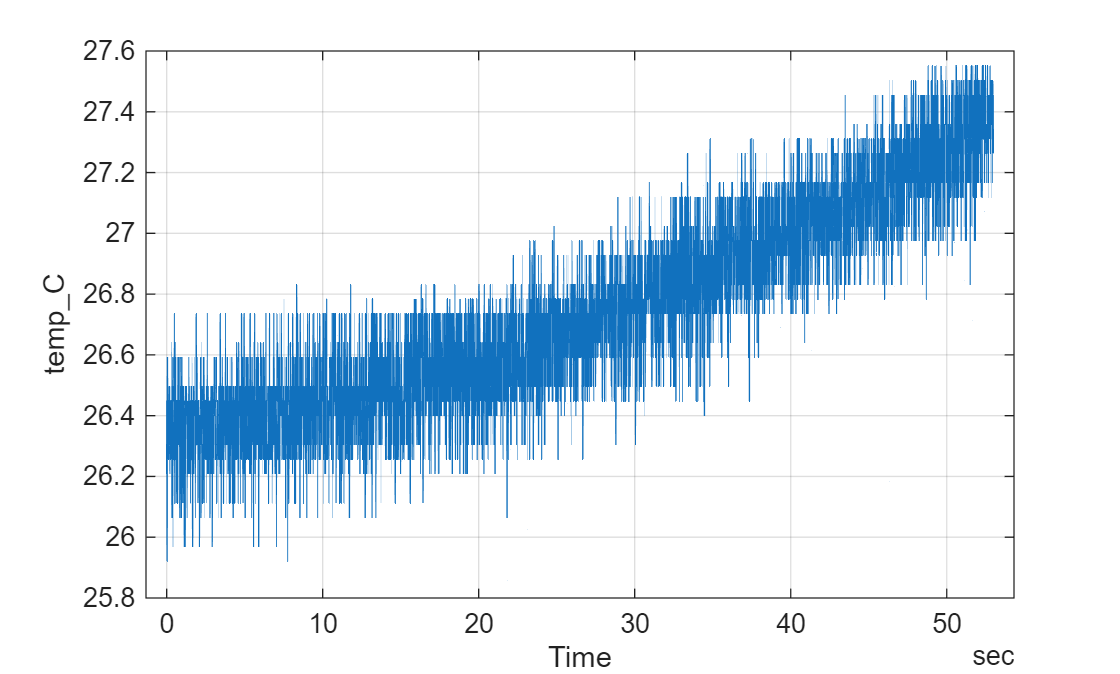


%temp vs time
figure; 
plot(imuTT,"temp_C");
grid on;

## Asses timing charachtaristics


===== IMU Timing Analysis =====
Mean sample period : 0.009618 s
Mean sampling rate : 104.400 Hz
Std period         : 1.244489e-04 s
RMS jitter         : 1.244376e-04 s
Peak jitter        : 9.226871e-03 s
Min dt             : 0.000391 s
Max dt             : 0.009620 s
Dropped samples    : 0


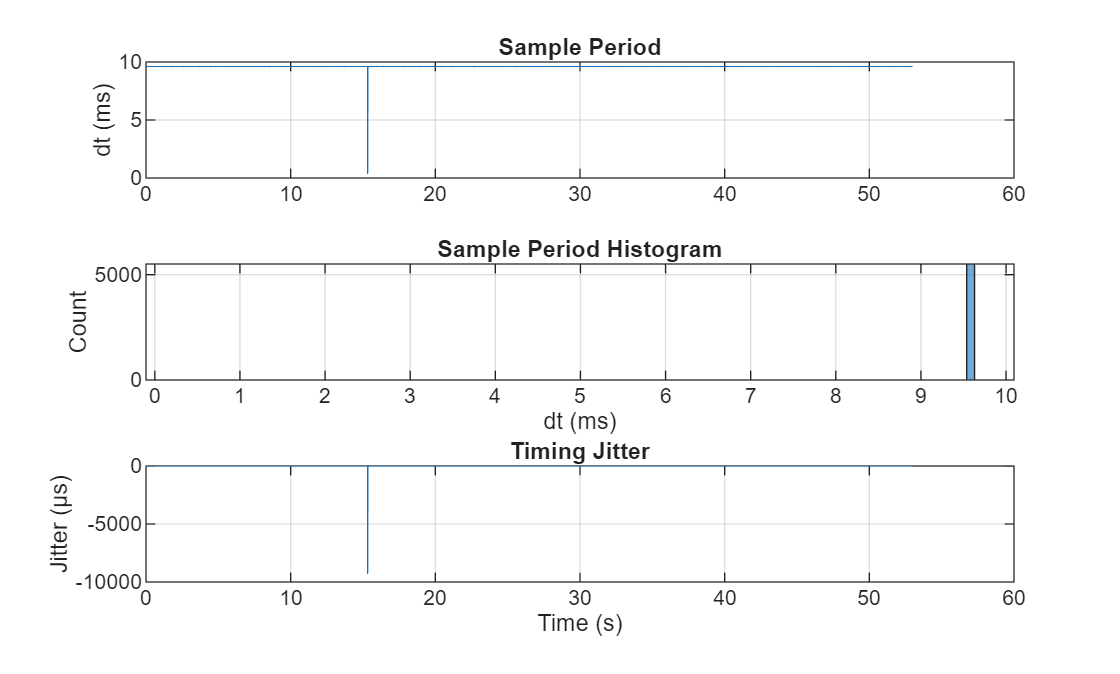

timeStats = imuTimingAnalysis(data);